# 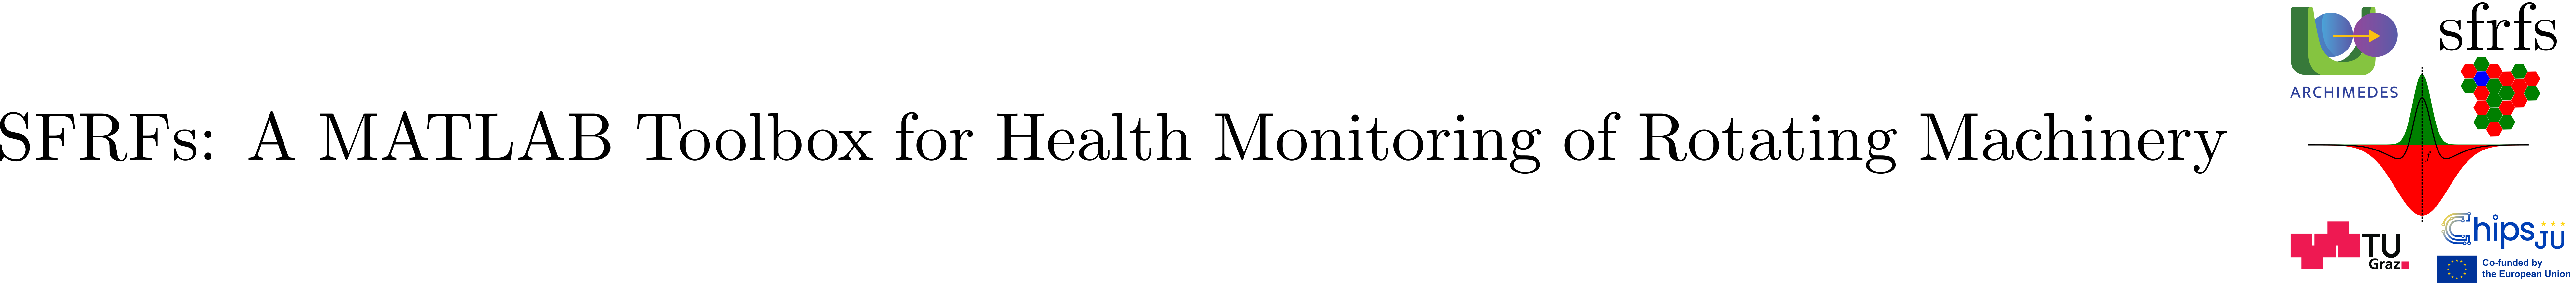

# EnsembleBroker

## Summary

`EnsembleBroker` is a concrete wrapper class that provides a uniform, metadata-aware interface to arbitrary ensemble-like data sources. It encapsulates a user-supplied ensemble object and delegates file retrieval to a provided function handle, ensuring complete flexibility in how ensemble member files are defined and organized.

**Key features:**

- Flexible data wrapping: Stores an arbitrary ensemble object and retrieves member file identifiers through a customizable function handle.

- Metadata management: Maintains ensemble-level information including temporal snapshot column names, the sorting field, the MAT-file variable name storing the member table, and the spectral suffix for frequency-domain representations.

- Bidirectional column mapping: Offers `mapToSpectralColumn` and `mapToTemporalColumn` utilities for consistent naming between time-domain and spectral domain signals.

- Standardized loading and saving: Provides static methods `saveEnsembleMember` and `loadEnsembleMember` for consistent MAT-file serialization, including validation, sorting, and control over variable naming.

- Robust validation: Validates all constructor arguments and metadata to safeguard correctness and avoid downstream inconsistencies.

`EnsembleBroker` serves as the central access layer within the SFRFs toolbox, standardizing how ensemble members are discovered, loaded, saved, and interpreted while remaining fully adaptable to different data formats and organizational schemes.

## Description

`EnsembleBroker` is a concrete wrapper class that standardizes access to ensemble-like data sources. The class encapsulates an arbitrary ensemble object and delegates the retrieval of member file identifiers to a user-provided function handle, enabling full flexibility in how ensemble members are organized and accessed. It stores ensemble-level metadata such as temporal snapshot column names, the sorting field, the MAT-file variable name that contains the member table, and the spectral suffix used for naming frequency-domain representations.

`EnsembleBroker` provides bidirectional column-mapping utilities that relate temporal signal columns to their spectral counterparts via `mapToSpectralColumn()` and `mapToTemporalColumn()`, ensuring naming consistency throughout the processing pipeline. It also defines standardized static helper methods for saving and loading ensemble member tables, including validation, variable-renaming, and sorting according to the configured metadata fields. Robust constructor validation ensures that all components of the broker are well-formed, allowing downstream processors to rely on the integrity of the ensemble structure.

### Public properties

### Public methods

### Static methods

## Example

### Object creation

To create the ensemble broker we need to pass the ensemble first. To illustrate the functionality we can use the available [EnsembleMock](matlab:open('../../../tests/EnsembleMock.m')) class, an auxiliary class for unit tests. 

#### Mock ensemble

The EnsembleMock creates a temporary folder and saves ensemble files with random data.

% Values from Wang et al.'s XJTU-SY datases.
% Create the snapshot parameters
sp = ParametersSnapshot(...
    'samplingFrequency', 25600, ...
    'duration', 1.28, ...
    'stride', 60);
% Define speeds and loads of the test
speeds = [35; 37.5; 40];
loads  = [12; 11; 10];

% Initialize and prepare EnsembleMock
ensembleMock = EnsembleMock( ...
    'numMembers', 3, ...
    'nSamples', sp.getTotalSamples(), ...
    'speeds', speeds, ...
    'loads', loads);

% Creates temp folder and saves ensemble files with random data
ensembleMock.prepare();        

% print a summary of first member of mock ensemble
firstMember = read(ensembleMock.fileEnsembleDS);
summary(firstMember)


firstMember: 9×5 table

Variables:

    HorizontalAcceleration: cell
    VerticalAcceleration: cell
    Speed: double
    Load: double
    SnapshotIndex: double

Statistics for applicable variables:

                              NumMissing     Min      Median     Max       Mean        Std    

    HorizontalAcceleration        0                                                           
    VerticalAcceleration          0                                                           
    Speed                         0           35        35        35        35             0  
    Load                          0           12        12        12        12             0  
    SnapshotIndex                 

#### EnsembleBroker creation

% Name of the columns containing the raw signals
temporalSnapshotColumns = {...
    'HorizontalAcceleration', 'VerticalAcceleration'};

% These parameters are the defaults, but can be changed programmatically
% Sort field, in this case the snapshot index
% sortField = "SnapshotIndex";

% Variable name inside MAT-files storing member table
% memberTableVarName = "ensembleMemberTable";

% Create broker
broker = SFRFsEnsembleBroker( ...
    'ensembleObject', ensembleMock.fileEnsembleDS, ...
    'getFilesFunction', @(obj) obj.Files, ...
    'temporalSnapshotColumns', temporalSnapshotColumns)

broker =   SFRFsEnsembleBroker with properties:

        sfrfsSuffixInternal: "_SFRFs"
                   ensemble: [1×1 fileEnsembleDatastore]
                  sortField: "SnapshotIndex"
         memberTableVarName: "ensembleMemberTable"
    temporalSnapshotColumns: {'HorizontalAcceleration'  'VerticalAcceleration'}
             spectralSuffix: "_FFT"



% To configure additional fields in the broker, include them as parameters 
% in the constructor call:
% testCase.brokerFFT = SFRFsEnsembleBroker( ...
%     ensembleObject = ensembleMockFFT.fileEnsembleDS, ...
%     getFilesFunction = @(obj) obj.Files, ...
%     temporalSnapshotColumns = temporalSnapshotColumns, ...
%     memberTableVarName = memberTableVarName);


#### Mock ensemble clean-up

Finally, we delete the temporary folder an files.

ensembleMock.cleanup()

## API documentation

### MATLAB help

help EnsembleBroker

  EnsembleBroker Concrete wrapper for ensemble-like objects.
 
    Wraps an arbitrary ensemble object and delegates the getFiles call
    to a provided method handle.
    Example:
        broker = SFRFsEnsembleBroker( ...
            'ensembleObject', fileEnsembleDS, ...
            'getFilesFunction', fcnHandle, ...
            'temporalSnapshotColumns', temporalSnapshotColumns)
 
    See also: EnsembleBroker/getFiles

    Documentation for EnsembleBroker
       doc EnsembleBroker




### MATLAB documentation

doc EnsembleBroker

Opens the full class documentation in the MATLAB Help Browser, including formatted examples, links to related functions, and extended descriptions.

## Source code

Source for the class is available in [EnsembleBroker](matlab:open('../../EnsembleBroker.m')).

## Test

Unit testing for the class is implemented in [TestEnsembleBroker](matlab:open('../../../tests/TestEnsembleBroker.m')).

% execute tests
res = runtests('Spectral Fault Receptive Fields/tests/TestEnsembleBroker');

Running TestEnsembleBroker
.......... .....
Done TestEnsembleBroker
__________



% display summary of tests
SFRFsTestUtil.printTestSummary(res,80);

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
TestEnsembleBroker/testGetFilesReturnsCorrectFiles                               | Passed
TestEnsembleBroker/testConstructorRejectsEmptyEnsemble                           | Passed
TestEnsembleBroker/testConstructorRejectsMissingGetFilesFunction                 | Passed
TestEnsembleBroker/testConstructorRejectsMissingEnsembleObject                   | Passed
TestEnsembleBroker/testConstructorRejectsMissingTemporalSnapshotColumns          | Passed
TestEnsembleBroker/testConstructorRejectsInvalidTemporalSnapshotColumns          | Passed
TestEnsembleBroker/testSaveAndLoadEnsembleMember                                 | Passed
TestEnsembleBroker/testSaveEnsembleMemberRejectsBadVarName                       | Passed
TestEnsembleBroker/testDefaultSpectralSuffix                                     | Passed
TestEnsemb

## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- Biao Wang, Yaguo Lei, Naipeng Li, Ningbo Li, “A Hybrid Prognostics Approach for Estimating Remaining Useful Life of Rolling Element Bearings”, IEEE Transactions on Reliability, pp. 1-12, 2018. [DOI: 10.1109/TR.2018.2882682](https://doi.org/10.1109/TR.2018.2882682).